# Design of PID Controller

This script illustrates the design of a PID controller for a feedback system with forward gain


$$G(s) = \frac{0.7}{(s+4)(s^2+1.7s+0.25)},$$


and feedback gain


$$H(s) = \frac{0.5}{s+0.5}.$$


The system is operating without compensation with a rise time approximately the same as a 2nd order system with peak time of 16 sec and 5% overshoot. There is also considerable steady-state error. Our task is to design a PID controller so that the compensated system will have a response approximately equivalent to a 2nd order system with a peak-time of 8 seconds and 5% overshoot, and zero steady-state error for a step input.

## Characterization of Uncompensated System

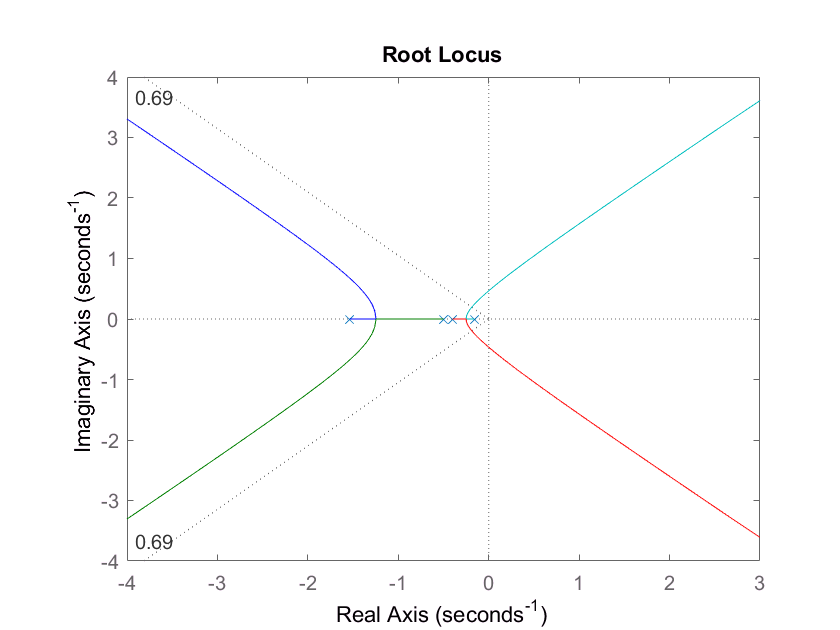

% Specifying overshoot
OS = 0.05;

% Computing zeta
zeta = -log(OS)/sqrt(pi^2 + log(OS)^2);

% Defining the open loop Gain G(s)H(s)
G = tf(0.7,conv([1 0.4],[1 1.7 0.25]));
H = tf(0.5,[1 0.5]);
GH = G*H;

% Plotting root locus
rlocus(GH);
sgrid(zeta,0);


% Defining range of finding intercept with zeta line from diagram
rMax = 1;

% Finding crossing
[sOut,KOut] = fnc_rootLocusCrossing(G*H,zeta,rMax);

% Displaying results
fprintf('jw-intercept at %5.3f+%5.3fj with K = %6.2f\n',real(sOut),...
    imag(sOut),KOut);

jw-intercept at -0.186+0.195j with K =   0.08



% Computing the equivalent transfer function with the gain computed above
Ge = feedback(KOut*G,H);

% Extracting the poles of the system. The higher order pole needs to be at
% least 5 times further away from the jw-axis than the dominant poles in order
% to have a good 2nd order approximation.
[num,den] = tfdata(Ge,'v');
poles = roots(den)

poles =   -1.5188 + 0.0000i
  -0.7071 + 0.0000i
  -0.1871 + 0.1958i
  -0.1871 - 0.1958i



% Computing the steady state error for an step input. We use the equivalent
% transfer function
e_Step = 1-evalfr(Ge,0)

e_Step = 0.6349

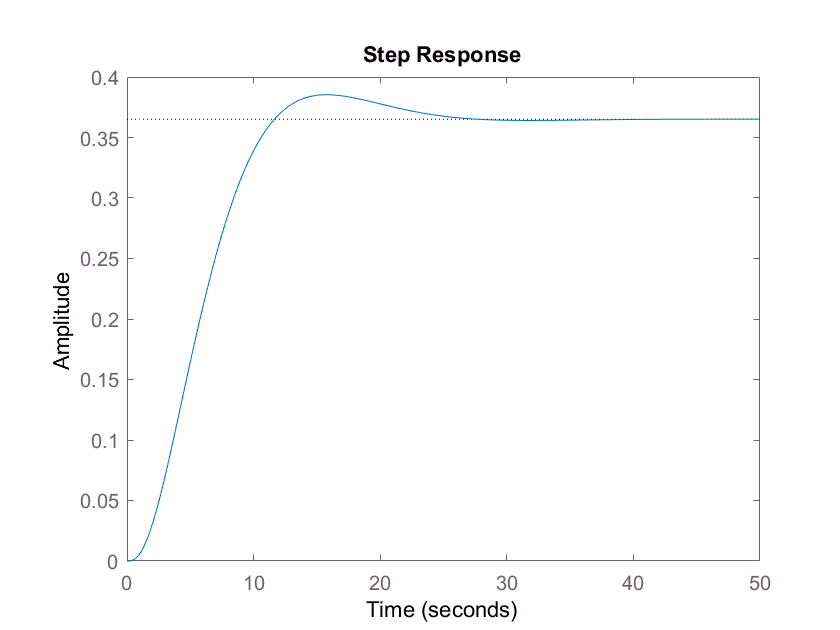


% Plotting step response of the equivalent system
step(Ge,50);

## Design of PD Controller

Our objective in this section is to modify the root locus of the system by adding a new zero to the system such as the peak time is reduced by a factor of two.

% Choosing the new dominant pole that reduces the peak time by 2
p1 = 2*sOut;

% Computing poles and zeros of G(s)H(s)
[num den] = tfdata(GH,'v');
zGH = roots(num);
pGH = roots(den);

% Computing the angle needed for zero
zAng = pi;
for i = 1:length(zGH)
    zAng = zAng - phase(p1-zGH(i));
end
for i = 1:length(pGH)
    zAng = zAng + phase(p1-pGH(i));
end
zAng = mod(zAng,2*pi);
fprintf('Angle for zero = %5.1f degrees\n',zAng*180/pi);

Angle for zero = 114.8 degrees



% Computing the location of the zero
zc = real(p1) - imag(p1)/tan(zAng);
fprintf('Zero located at zc = %5.2f\n',zc);

Zero located at zc = -0.19


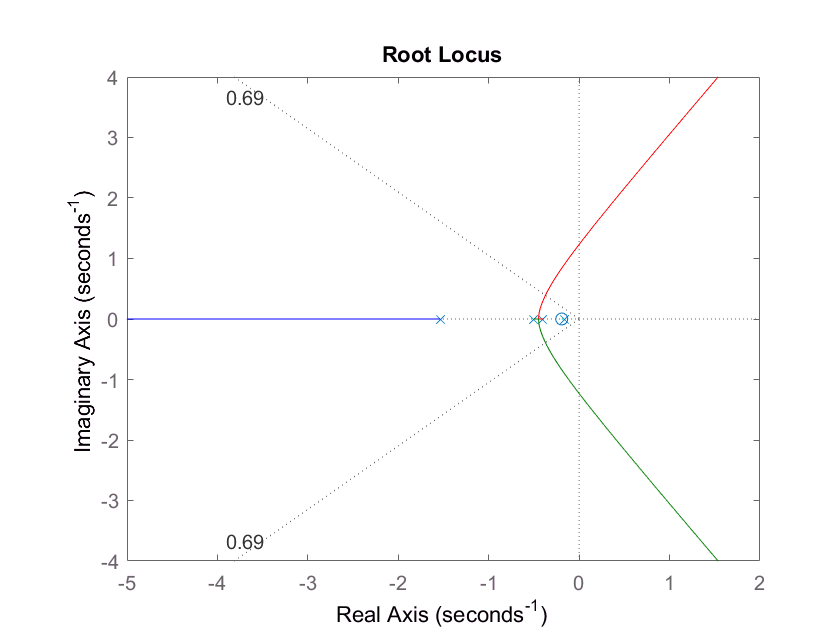


% Defining the PD Compensator
Gc1 = tf([1 -zc],1);

% Plotting root locus
rlocus(G*Gc1*H);
sgrid(zeta,0);



% Defining range of finding intercept with zeta line from diagram
rMax = 1;

% Finding crossing
[sOut_C1,KOut_C1] = fnc_rootLocusCrossing(G*Gc1*H,zeta,rMax);

% Displaying results
fprintf('jw-intercept at %5.3f+%5.3fj with K = %6.2f\n',real(sOut_C1),...
    imag(sOut_C1),KOut_C1);

jw-intercept at -0.373+0.391j with K =   0.58


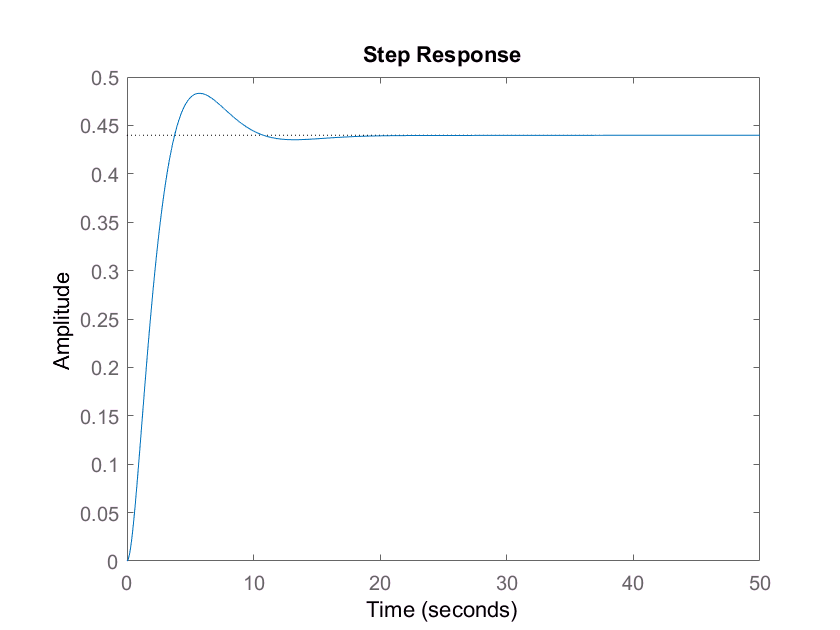


% Computing the equivalent transfer function with the gain computed above
Ge_C1 = feedback(KOut_C1*G*Gc1,H);

% Plotting step response of the equivalent system
step(Ge_C1,50);

## Desing of PID Controller

We need to add a PI controller next and refine the parameter choices if needed.

% We add a PI Compensator with a zero at -0.01 (try values up to -0.3)
Gc2 = tf([1 0.25],[1 0]);

% Plotting the locus
%rlocus(Gc2*Gc1*G*H);
%sgrid(zeta,0);

% Defining range of finding intercept with zeta line from diagram
rMax = 1;

% Finding crossing
[sOut_C2,KOut_C2] = fnc_rootLocusCrossing(G*Gc1*Gc2*H,zeta,rMax);

% Displaying results
fprintf('jw-intercept at %5.3f+%5.3fj with K = %6.2f\n',real(sOut_C2),...
    imag(sOut_C2),KOut_C2);

jw-intercept at -0.288+0.303j with K =   0.62


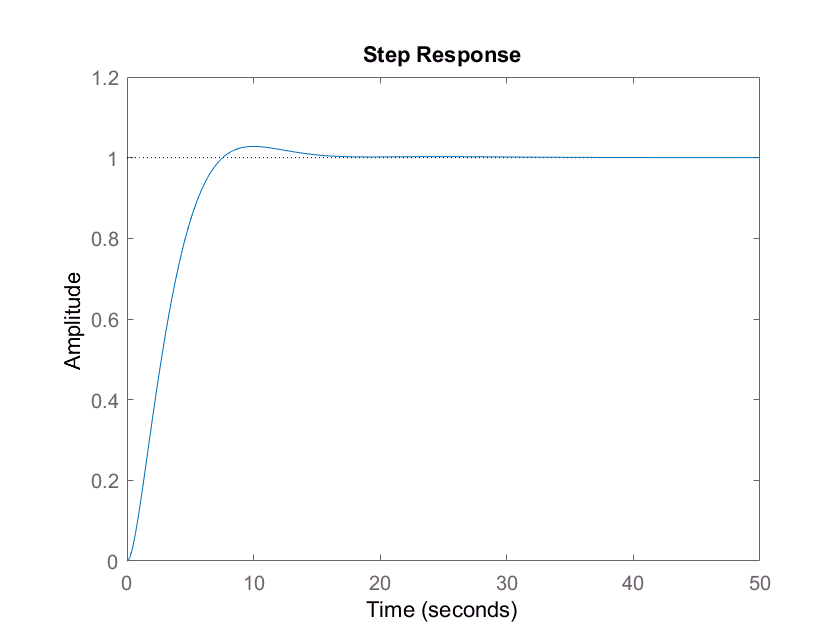


% Computing the equivalent transfer function with the gain computed above
Ge_C2 = feedback(KOut_C2*G*Gc1*Gc2,H);

% Plotting step response of the equivalent system
step(Ge_C2,50);